# Using the oiCompute function

The optics transform the scene spectral radiance into the sensor irradiance. In ISETCam the key function that manages this transformation is **oiCompute**.

ISETCam uses the term optical image (oi) to refer to the data structure that describes the  the spectral irradiance at the sensor. The conversion of the scene radiance to spectral radiance is  determined by the parameters of the **optics,** which is another data structure attached to the oi object (**oi.optics**)

**See also:  **oiCompute, t_oiIntroduction, t_sceneIntroduction, t_optics

ieInit

## Create a Scene and oi (irradiance) Image from an array of points

It is very convenient to analyze the optics  using an array of points of light as inputs (the scene radiance) and measuring the image that is formed by the optics (sensor irradiance).  To understand how the optics blurs the points.

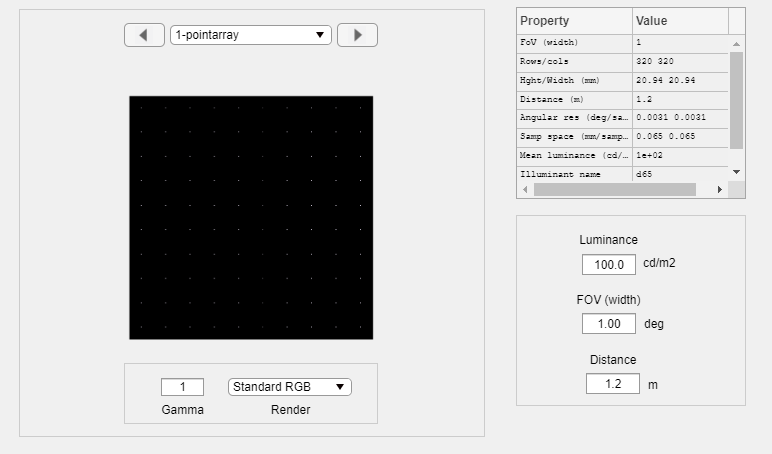

% [row,col], point spacing
scene = sceneCreate('point array',[320 320],32);   
scene = sceneSet(scene,'hfov',1);  % Horizontal field of view 1 deg
sceneWindow(scene);

## Diffraction limited optics

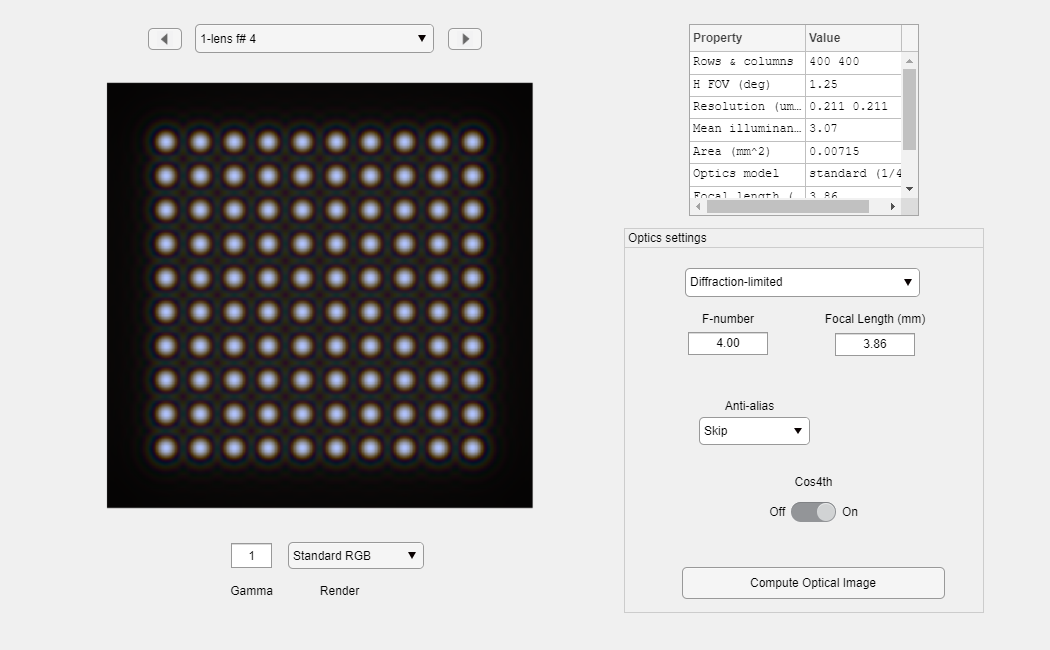

% Create default optical image uses a diffraction limited lens
oi = oiCreate;                       

% Compute optical image and show it
oi = oiCompute(scene,oi);
fnSmall = oiGet(oi,'optics f number');
oi = oiSet(oi,'name',sprintf('lens f# %d\n',fnSmall));
oiWindow(oi);

## Increase the f-number (f/#), Compute and Show the new Image

For diffraction-limited optics, the f-number is the critical parameter.  Let's have a look at the sensor irradiance when we increase the f-number.

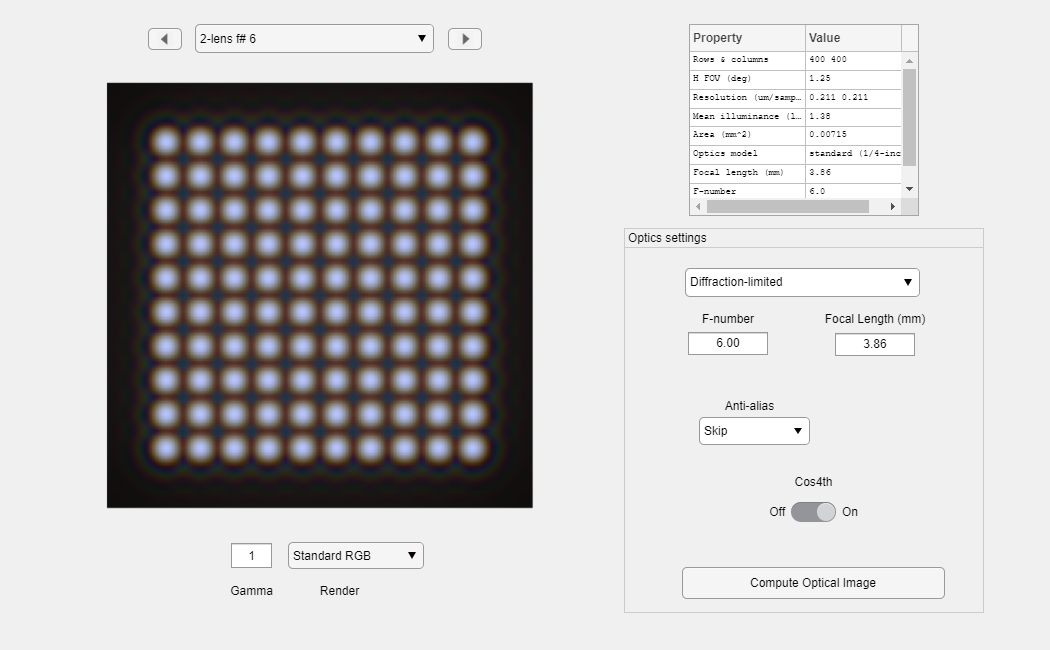

% Increase the f-number
fnBig   = 1.5 * fnSmall;
oi2 = oiSet(oi,'optics fnumber',fnBig);

% Compute again and have a look
oi2 = oiCompute(scene,oi2);
oi2 = oiSet(oi2,'name',sprintf('lens f# %d\n',fnBig));
oiWindow(oi2);

## Plot the Pointspread Function (psf) of the Optics

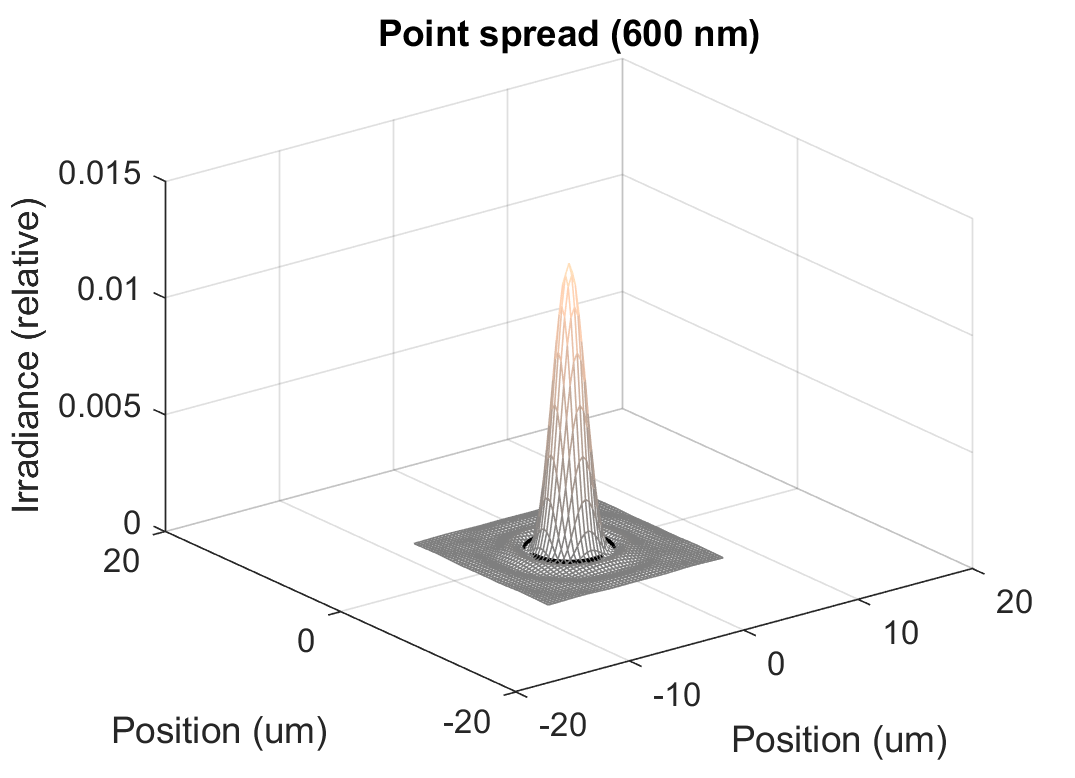

ieNewGraphWin;
thisWave = 600;   % 600 nm
oiPlot(oi,'psf',[],thisWave);
set(gca,'xlim',[-20 20],'ylim',[-20 20]);
colormap(0.5*copper + 0.5*ones(size(copper)));

## Plot the Irradiance Image

Sometimes we just make a plot, rather than look within the oiWindow.

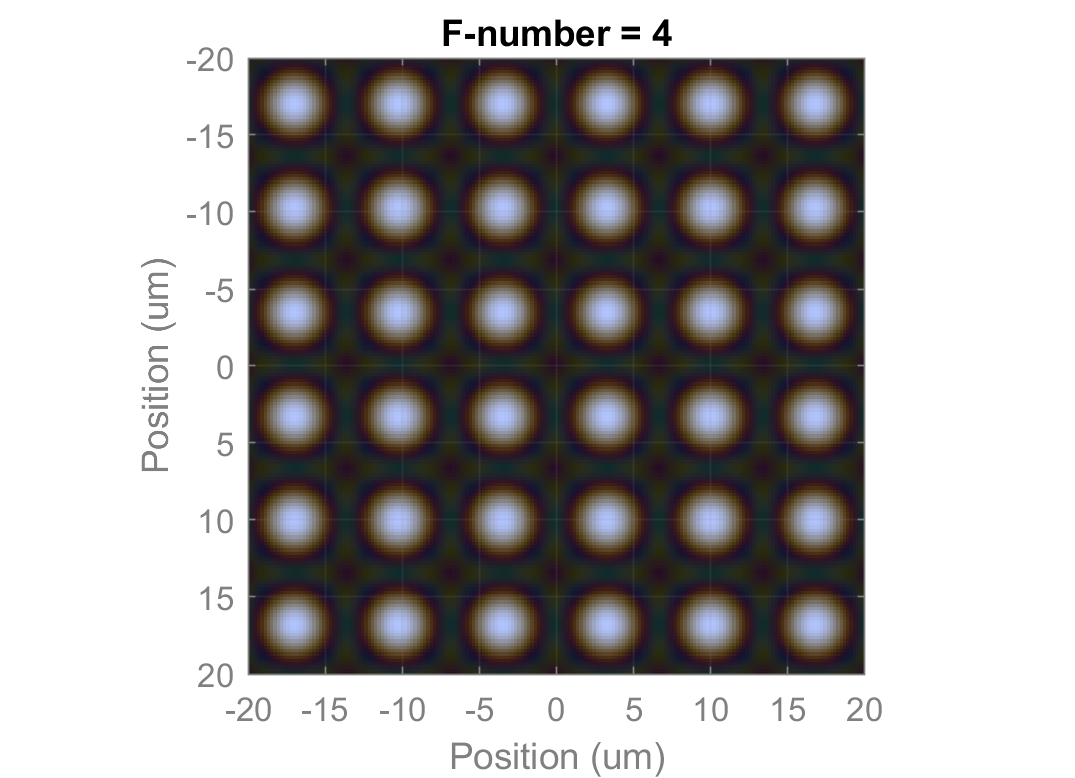

ieNewGraphWin;
gridSpacing = 5; % um
oiPlot(oi,'irradiance image with grid',[],gridSpacing);
set(gca,'xlim',[-20 20],'ylim',[-20 20])
title(sprintf('F-number = %d',fnSmall))

## Change the f/# (f-number) of the Optics and Re-plot

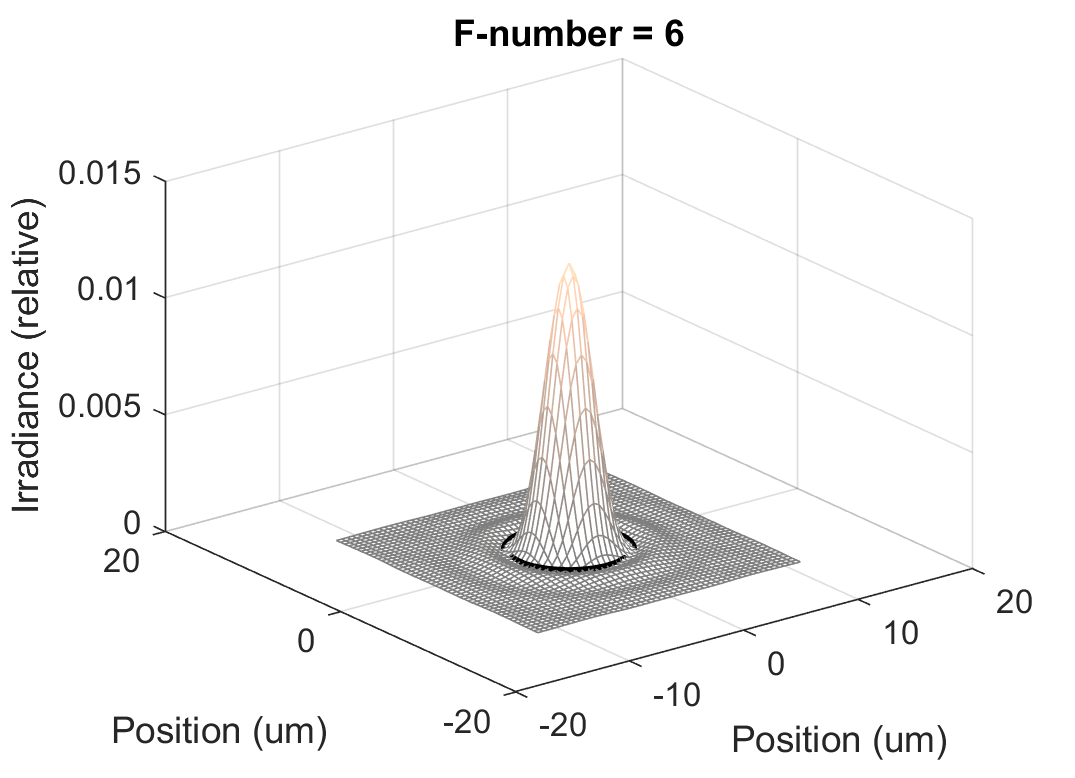

ieNewGraphWin;
oiPlot(oi2,'psf',[],thisWave);
set(gca,'xlim',[-20 20],'ylim',[-20 20])

colormap(0.5*copper + 0.5*ones(size(copper)))
title(sprintf('F-number = %d',fnBig))

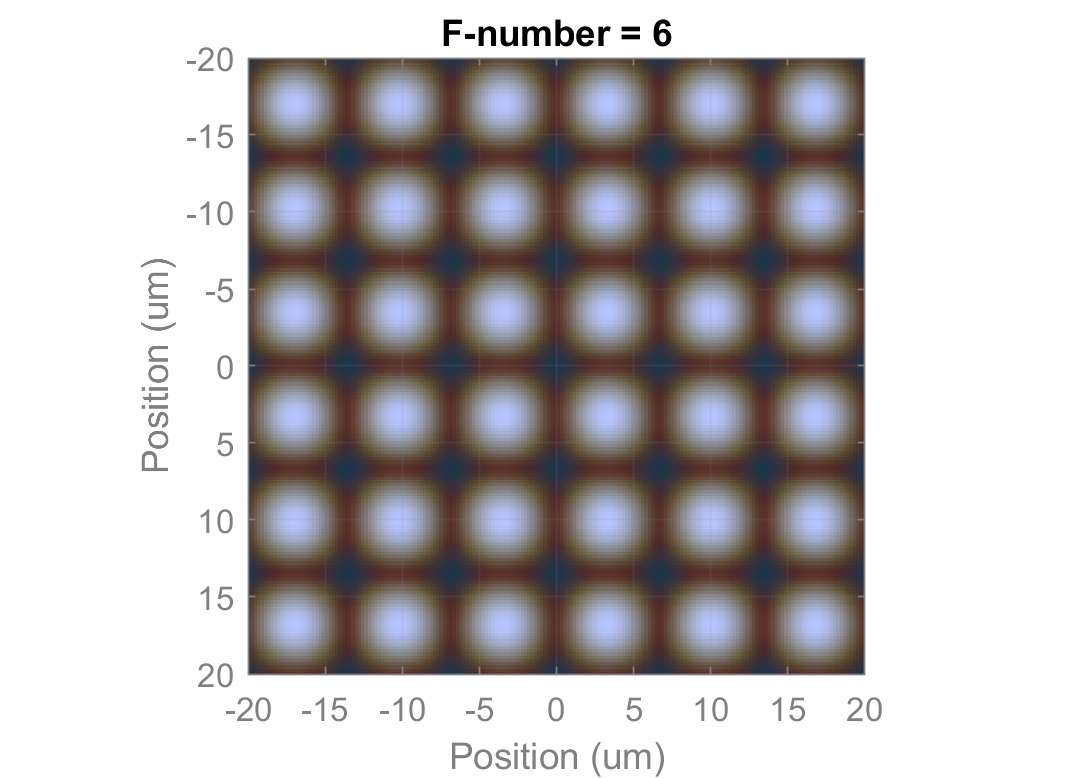


ieNewGraphWin;
gridSpacing = 5;
oiPlot(oi2,'irradiance image with grid',[],gridSpacing);
set(gca,'xlim',[-20 20],'ylim',[-20 20])
title(sprintf('F-number = %d',fnBig))